### Init and load torque from excel:

clear
load("airfoil.mat")
load("wing_opt.mat")
load("scr_s0.mat")
load("Farror.mat")
T = readtable("E - Wing Load.xlsx",'Sheet',"Wing Torque");

location = table2array(T(1:60,3));
M = table2array(T(1:60,25))*1e-3;
location = [-flip(location); location(2:end)];
M0 = [flip(M); M(2:end)];
M_interpolated = interp1(location, M0, wing_opt.stripy,'spline');
M = M_interpolated;
pltidx=1

pltidx = 1

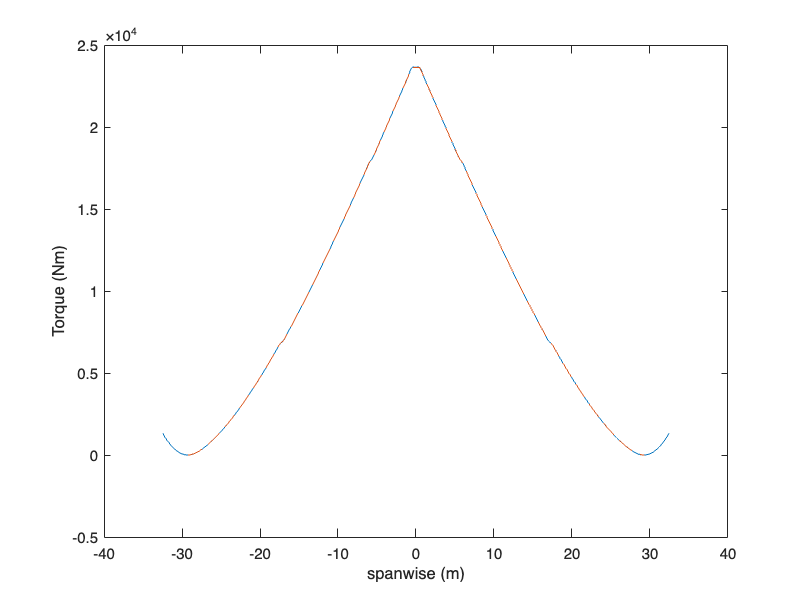

figure(pltidx)
clf;
plot(wing_opt.stripy, M)
hold on
plot(location, M0,'--')
xlabel("spanwise (m)")
ylabel("Torque (Nm)")

pltidx = pltidx + 1;

Material:

steel=material();
steel.E = 70e9;

## **WingBox geometry (unchanged throughout)**

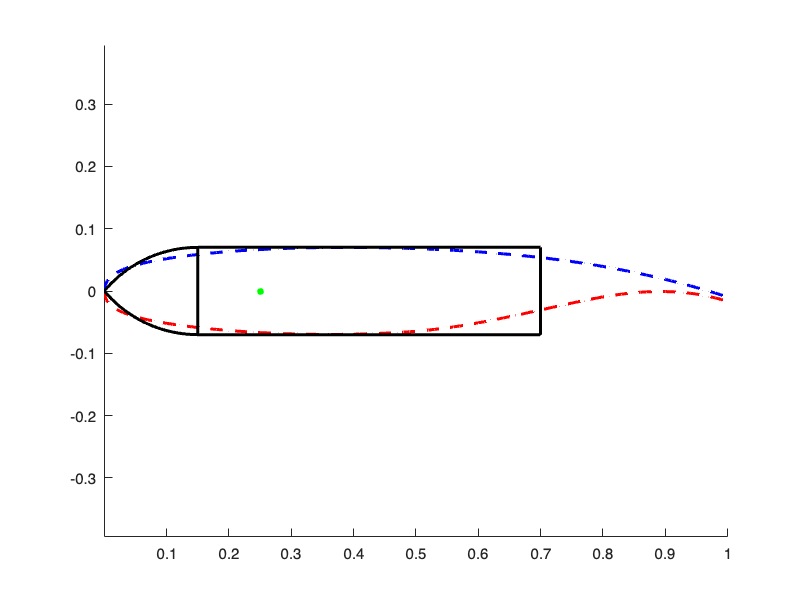

wb = wingbox();
%define geometry
wb.b2_c = 0.14;
wb.b_c = 0.15;
wb.c_c = 0.7 - wb.b_c;
wb = wb.calcR();
%define stringers
wb.L = 1;
%show wingbox:
figure(pltidx)
clf;
wb.drawwithAirfoil(airfoil)

pltidx = pltidx + 1;

wb.a = ones(length(wing_opt.stripy),1).*5;

## 1.skin buckling, variables are:

wb.N = 20;        % stringer number
wb.ts = 10e-3;    % stringer thickness
wb.hs = 80e-3;    % stringer height
wb.ds = wb.hs*0.3;% stringer width
wb = wb.calcb1();
wb = wb.calcStringerArea();

wb.t2 = 7.72e-3; % main cell thickness

Compute critical stresses (global and local)

wb = wb.interpsr_s0(scr_s0,wing_opt);
wb = wb.interpretF(F_data, wing_opt);

wbStress = wingboxStress();
wbStress.wb = wb;
wbStress = wbStress.findGlobalStress(M,wing_opt,steel);

Unrecognized function or variable 'sigma_0'.

Error in wingboxStress/findGlobalStress (line 24)
            obj.s_0_global_skin = sigma_0;

wbStress = wbStress.findLocalStress(M,wing_opt,steel);

Thickness parameters need to be optimized to give equal global and local buckling stress

figure(pltidx)
pltidx = pltidx + 1;
clf;
hold on
plot(wing_opt.stripy, wbStress.s_cr_global_skin);
hold on
plot(wing_opt.stripy, wbStress.s_cr_local_skin);
legend("Local, Farror","Global, Euler")
xlabel("y (m)")
ylabel("$\sigma$","Interpreter","latex")
xlim([0 wing_opt.s])

## **2. Spar buckling analysis(get spar thickness)**

**Web is fixed at top/bottom, SS at sides (web stringers)**

[t_FS, t_RS] = Sparfun(wb, wing,material,V,T,wbStress)

## 3. Dcell

%guessed D cell skin thickness
t1 = 0.01;
t = Dcellfun(wb,wing_opt,wing_opt.b/2,steel,t1)

  1×3 string array

    "size of a:"    "301"    "1"

x_val = 6.3433
a/b = 9.5238
lower_idx = 4, upper_idx = 5
Computed Ks = 11.8052
x_val = 6.3999
a/b = 9.356
lower_idx = 4, upper_idx = 5
Computed Ks = 11.9192
x_val = 6.456
a/b = 9.1941
lower_idx = 4, upper_idx = 5
Computed Ks = 12.0326
x_val = 6.5117
a/b = 9.0377
lower_idx = 4, upper_idx = 5
Computed Ks = 12.1453
x_val = 6.5668
a/b = 8.8864
lower_idx = 4, upper_idx = 5
Computed Ks = 12.2575
x_val = 6.6215
a/b = 8.7402
lower_idx = 4, upper_idx = 5
Computed Ks = 12.3691
x_val = 6.6758
a/b = 8.5987
lower_idx = 4, upper_idx = 5
Computed Ks = 12.4801
x_val = 6.7296
a/b = 8.4617
lower_idx = 4, upper_idx = 5
Computed Ks = 12.5905
x_val = 6.783
a/b = 8.329
lower_idx = 4, upper_idx = 5
Computed Ks = 12.7004
x_val = 6.836
a/b = 8.2004
lower_idx = 4, upper_idx = 5
Computed Ks = 12.8097
x_val = 6.8885
a/b = 8.0758
lower_idx = 4, upper_idx = 5
Computed Ks = 12.9185
x_val = 6.9407
a

t =     0.0065    0.0065    0.0066    0.0067    0.0068    0.0069    0.0070    0.0070    0.0071    0.0072    0.0073    0.0074    0.0074    0.0075    0.0076    0.0077    0.0078    0.0078    0.0079    0.0080    0.0081    0.0081    0.0082    0.0083    0.0084    0.0084    0.0085    0.0086    0.0087    0.0087    0.0088    0.0089    0.0090    0.0090    0.0091    0.0092    0.0092    0.0093    0.0094    0.0095    0.0095    0.0096    0.0097    0.0097    0.0098    0.0099    0.0100    0.0100    0.0101    0.0102


**4.**